0. Задаем длину интервала $L$, число точек $N$, левую границу зеркала $x_l$, правую границу зеркала $x_r$.

clear all;
L=1; % длина интервала
N=512; % число точек
dx = L/N; % шаг по x
x=0:L/N:L*((N-1)/N); % вектор {x_j}
xl=0.35*L; % начало зеркала (xr - зекально относительно центра в L/2)
xr=L-xl; % конец зеркала
ixl = round(xl/dx); % индекс левого края зеркала
ixr = N - ixl + 2; % индекс правого края зеркала
k=0:N-1; % номера гармоник

1. Задаем функцию зекала $R\left(x\right)$:

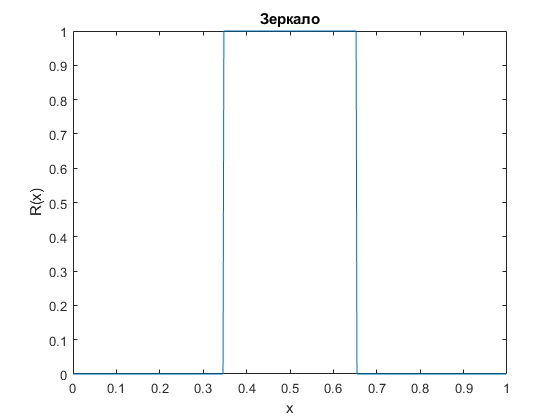

R=zeros(N,1); R(1:ixl-1) = 0; R(ixl:ixr) = 1; R(ixr+1:end) = 0; % зеркальце в середине интыервала (N+1 точка)
plot(x,R); title('Зеркало'); xlabel('x'); ylabel('R(x)');

2.  Делаем дискретное синус-преобразование функции зеркала $\textrm{MirrDSTonN}\left(R\left(x\right)\right)$:

MirrDSTonN = sintr(R);

3. Вычисляем $N$гармоник синус-преобразования зеркала по аналитической формуле $\textrm{MirrTSTonN}\left(R\left(x\right)\right)$:

MirrTSTonN = [0 2./(k(2:end)*pi).*(cos(k(2:end)*pi*xl/L)-cos(k(2:end)*pi*xr/L))];

4. Сравниваем графики. Аналитическое выражение для гармоник нужно умножить на $\sqrt{\frac{2}{N}}$, чтобы оно соответствовало дискретному аналогу.

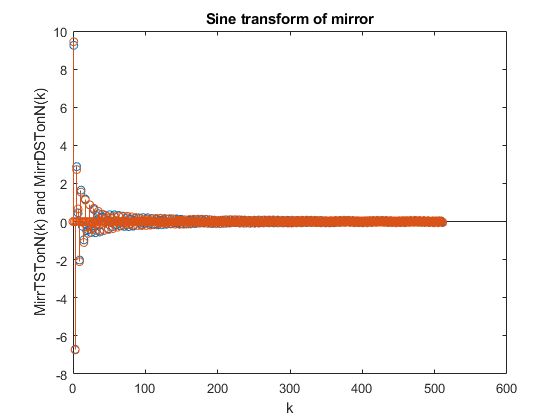

stem(k, MirrTSTonN/sqrt(2/N))
hold on
stem(k,MirrDSTonN); title('Sine transform of mirror'); xlabel('k'); ylabel('MirrTSTonN(k) and MirrDSTonN(k)');
hold off

5. Обратное преобразование:

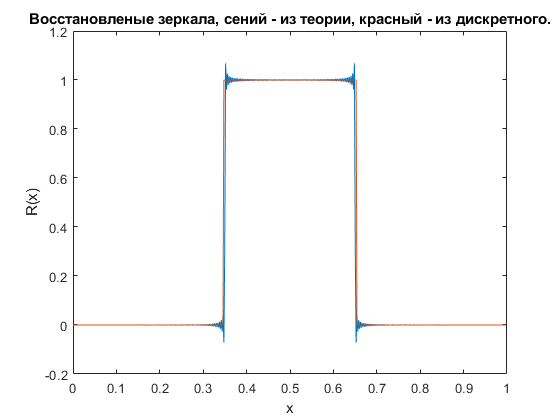

iMirrDSTonN = sintr(MirrDSTonN);
iMirrTSTonN = sintr(MirrTSTonN/sqrt(2/N));
plot(x,iMirrTSTonN)
hold on
plot(x,iMirrDSTonN)
hold off
title('Восстановленые зеркала, сений - из теории, красный - из дискретного.'); xlabel('x'); ylabel('R(x)');

6. Восстановим зеркало с половинным шагом и с шагом/3, из функций $\textrm{MirrTSTonN}$ и $\textrm{MirrDSTonN}$, полученной добавлением $N$ и $2N$ соответственно:

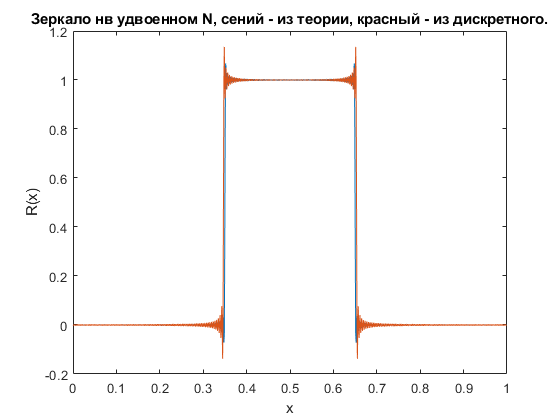

MirrTSTon2N = [MirrTSTonN zeros(1,N)]/sqrt(1/N); % заполняем нулями и умножаем на sqrt(2/(2*N))
iMirrTSTon2N = sintr(MirrTSTon2N); % обратное преобразование
iMirrDSTon2N = sintr(sqrt(2)*[MirrDSTonN' zeros(1,N)]);
dx2 = L/N/2; % половинный шаг по x
x2 = 0:dx2:L-dx2;
plot(x2,iMirrTSTon2N) % из аналитики (синий)
hold on
plot(x2,iMirrDSTon2N) % из дискретного преобразования (красный)
hold off
title('Зеркало нв удвоенном N, сений - из теории, красный - из дискретного.'); xlabel('x'); ylabel('R(x)');

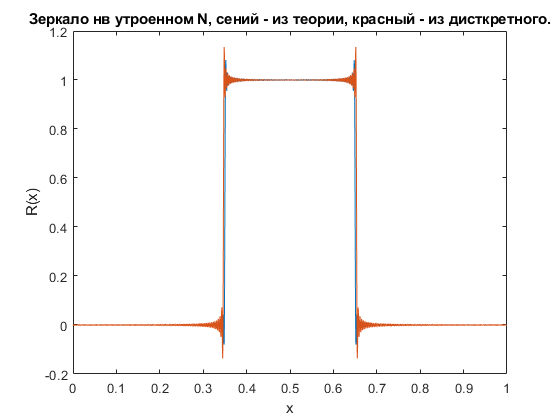


MirrTSTon3N = [MirrTSTonN zeros(1,2*N)]/sqrt(2/(3*N)); % заполняем нулями и умножаем на sqrt(2/(3*N))
iMirrTSTon3N = sintr(MirrTSTon3N); % обратное преобразование
iMirrDSTon3N = sintr(sqrt(3)*[MirrDSTonN' zeros(1,2*N)]);
dx3 = L/N/3;
x3 = 0:dx3:L-dx3;
plot(x3,iMirrTSTon3N) % из аналитики (синий)
hold on
plot(x3,iMirrDSTon3N) % из дискретного преобразования (красный)
title('Зеркало нв утроенном N, сений - из теории, красный - из дисткретного.'); xlabel('x'); ylabel('R(x)');
hold off

7. Для сравнения построим матрицу $R_{\textrm{pn}}$:

Rad = zeros(N,N); % матрица полученная дискретно
Rat = zeros(N,N); % матрица полученная из аналитики
j=0:N-1;
% R = 1; xl=0; xr=L; % для теста (сплошное зеркало)
for p=0:N-1
    for n=0:N-1
        Rad(p+1,n+1) = 2/N*sum(R'.*sin(pi*n*j/N).*sin(pi*p*j/N));
        if (n == 0 || p == 0)
            Rat(p+1,n+1) = 0;
        elseif (n == p)
            Rat(p+1,n+1) = (2*n*pi*(-xl + xr) + L*sin((2*n*pi*xl)/L) - L*sin((2*n*pi*xr)/L))/(2.*L*n*pi);
            mat(p+1,1:2) = [p Rat(p+1,n+1)];
        else
            Rat(p+1,n+1) = ((-sin(((n - p)*pi*xl)/L) + sin(((n - p)*pi*xr)/L))/(n - p) + ...
                (sin(((n + p)*pi*xl)/L) - sin(((n + p)*pi*xr)/L))/(n + p))/pi;
        end
    end
end
% mat=Rat(1:N,10);
% save('matlab.dat',"mat",'-ascii')

8. Отразим волну с помощю матрицы.

Сначала построим функцию, например гауссову: $u=3e^{\left(-\frac{{\left(x-0\ldotp 5L\right)}^2 }{0\ldotp 08}\right)}$

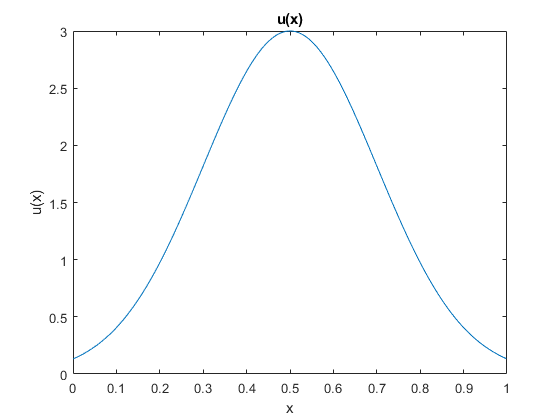

u=3*exp(-(x-L/2).^2/0.08);
plot(x,u)
title('u(x)'); xlabel('x'); ylabel('u(x)');

Сделаем синус-преобразование и нарисуем его:

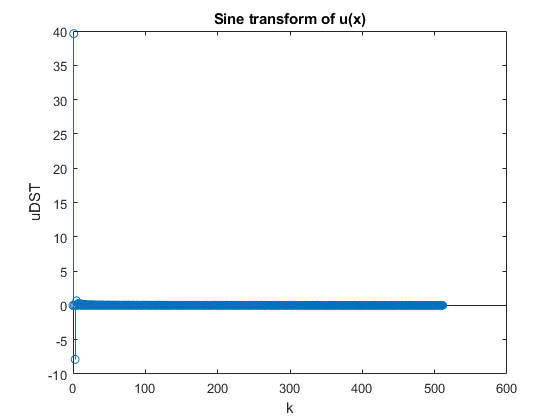

uDST=sintr(u);
stem(k,uDST); title('Sine transform of u(x)'); xlabel('k'); ylabel('uDST');

Обратное преобразование и сравнение с оригиналом:

iuDST = sintr(uDST);
plot(x,u,x,iuDST); title('u(x)'); xlabel('x'); ylabel('u(x) и iuDST(x)');

Умножим на матрицу, и построим то, что получилось:

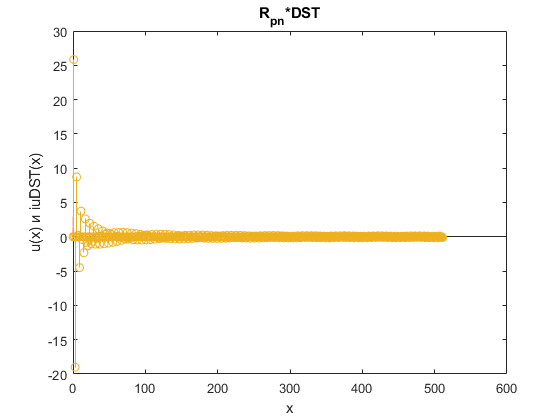

RatuDST=Rat*uDST;
RaduDST=Rad*uDST;
hold on
stem(k,RaduDST); title('R_{pn}*DST'); xlabel('x');
hold off

Теперь преобразуем обратно:

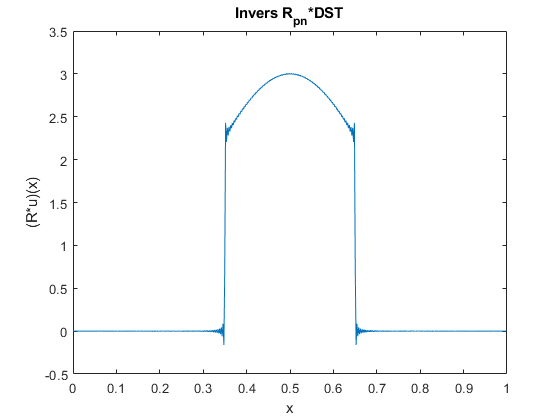

iRatuDST=sintr(RatuDST);
plot(x, iRatuDST); title('Invers R_{pn}*DST'); xlabel('x'); ylabel('(R*u)(x)');

 Получим тоже самое при поощи дискретного преобразования с половиннм шагом:

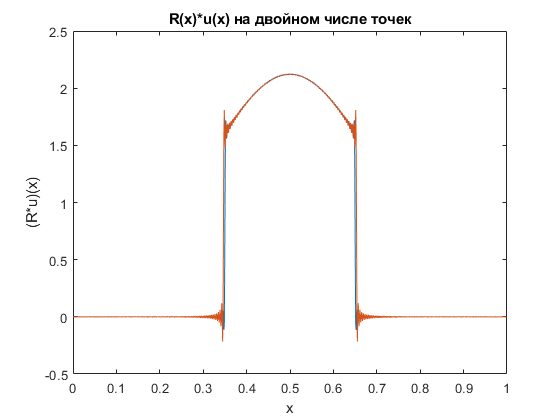

u2 = sintr(sqrt(2)*[uDST' zeros(1,N)]);
Ru2withMirrTSTon2N = u2.*iMirrTSTon2N/sqrt(2);
Ru2withMirrDSTon2N = u2.*iMirrDSTon2N/sqrt(2);
plot(x2,Ru2withMirrTSTon2N,x2,Ru2withMirrDSTon2N); title('R(x)*u(x) на двойном числе точек'); xlabel('x'); ylabel('(R*u)(x)');

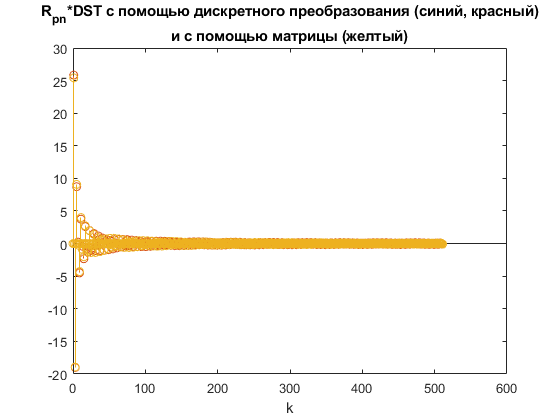

Ru2DSTon2NwithRu2withMirrTSTon2N = sintr(Ru2withMirrTSTon2N);
Ru2DSTon2NwithRu2withMirrDSTon2N = sintr(Ru2withMirrDSTon2N);
stem(k,Ru2DSTon2NwithRu2withMirrTSTon2N(1:N))
hold on
stem(k,Ru2DSTon2NwithRu2withMirrDSTon2N(1:N))
hold on
stem(k,RatuDST)
title({'R_{pn}*DST c помощью дискретного преобразования (синий, красный)'; 'и с помощью матрицы (желтый)'}); xlabel('k');
hold off

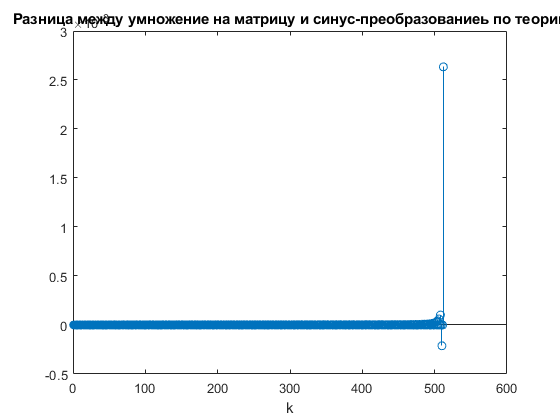

stem(Ru2DSTon2NwithRu2withMirrTSTon2N(1:N)-RatuDST); title('Разница между умножение на матрицу и синус-преобразованиеь по теории'); xlabel('k');

max(Ru2DSTon2NwithRu2withMirrTSTon2N(1:N)-RatuDST)

ans =    2.6342e-03

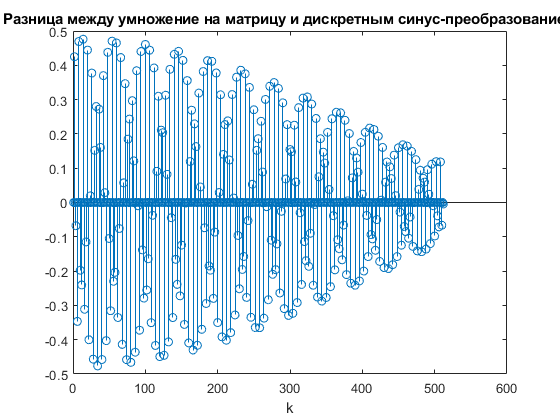

stem(Ru2DSTon2NwithRu2withMirrDSTon2N(1:N)-RatuDST); title('Разница между умножение на матрицу и дискретным синус-преобразованием'); xlabel('k');

max(Ru2DSTon2NwithRu2withMirrDSTon2N(1:N)-RatuDST)

ans =    4.7600e-01

Попробуем построить функцию из гармоник:

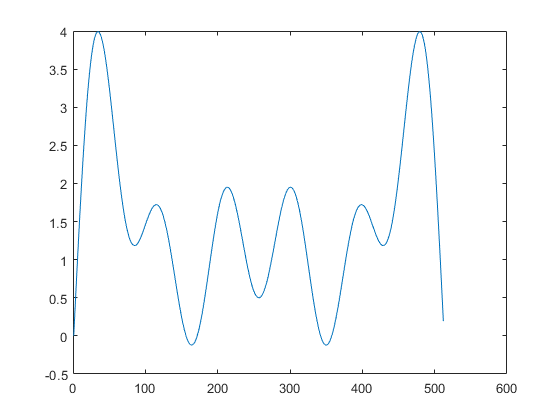

c = zeros(N,1);
c(1:12) = [0 25 0 17 0 21 0 12 0 7 0 16];
uc = sintr(c);
plot(uc)

Сделаем синус-преобразование и нарисуем его:

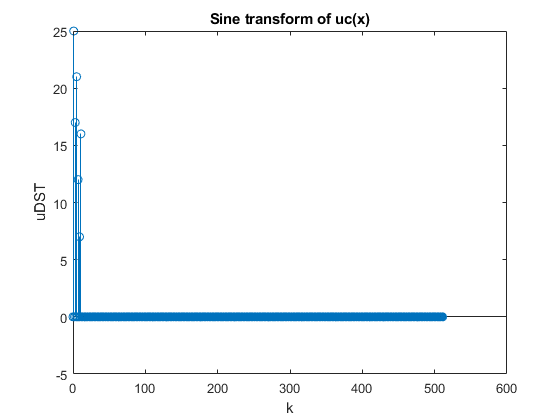

ucDST=sintr(uc);
stem(k,ucDST); title('Sine transform of uc(x)'); xlabel('k'); ylabel('uDST');

Обратное преобразование и сравнение с оригиналом:

iucDST = sintr(ucDST);
plot(x,uc,x,iucDST); title('uc(x)'); xlabel('x'); ylabel('uc(x) и iucDST(x)');

Умножим на матрицу, и построим то, что получилось:

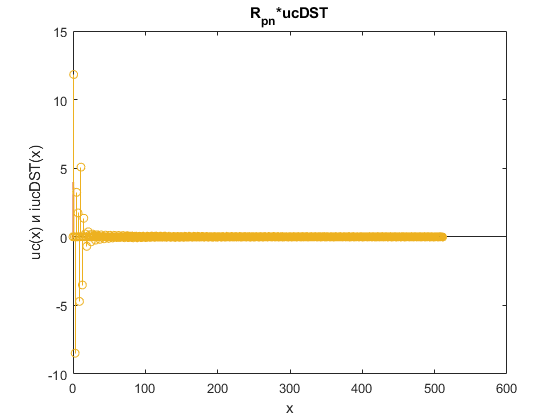

RatucDST=Rat*ucDST;
RaducDST=Rad*ucDST;
hold on
stem(k,RaducDST); title('R_{pn}*ucDST'); xlabel('x');
hold off

Теперь преобразуем обратно:

iRatuDST=sintr(RatuDST);
plot(x, iRatuDST); title('Invers R_{pn}*DST'); xlabel('x'); ylabel('(R*u)(x)');

 Получим тоже самое при поощи дискретного преобразования с половиннм шагом:

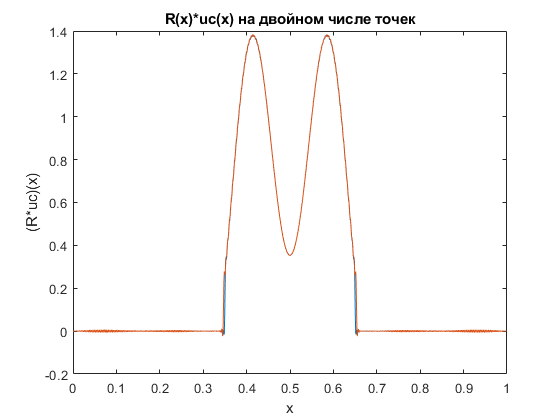

uc2 = sintr(sqrt(2)*[ucDST' zeros(1,N)]);
Ruc2withMirrTSTon2N = uc2.*iMirrTSTon2N/sqrt(2);
Ruc2withMirrDSTon2N = uc2.*iMirrDSTon2N/sqrt(2);
plot(x2,Ruc2withMirrTSTon2N,x2,Ruc2withMirrDSTon2N); title('R(x)*uc(x) на двойном числе точек'); xlabel('x'); ylabel('(R*uc)(x)');

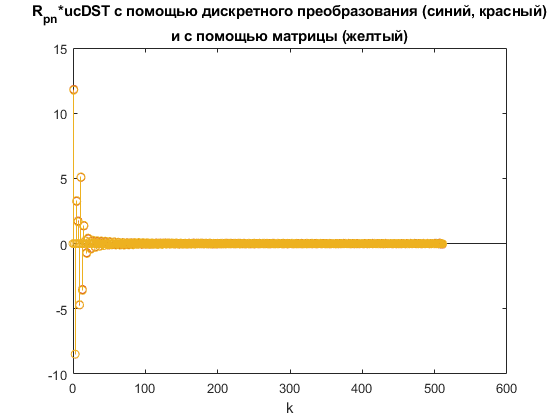

Ruc2DSTon2NwithRu2withMirrTSTon2N = sintr(Ruc2withMirrTSTon2N);
Ruc2DSTon2NwithRu2withMirrDSTon2N = sintr(Ruc2withMirrDSTon2N);
stem(k,Ruc2DSTon2NwithRu2withMirrTSTon2N(1:N))
hold on
stem(k,Ruc2DSTon2NwithRu2withMirrDSTon2N(1:N))
hold on
stem(k,RatucDST)
title({'R_{pn}*ucDST c помощью дискретного преобразования (синий, красный)'; 'и с помощью матрицы (желтый)'}); xlabel('k');
hold off

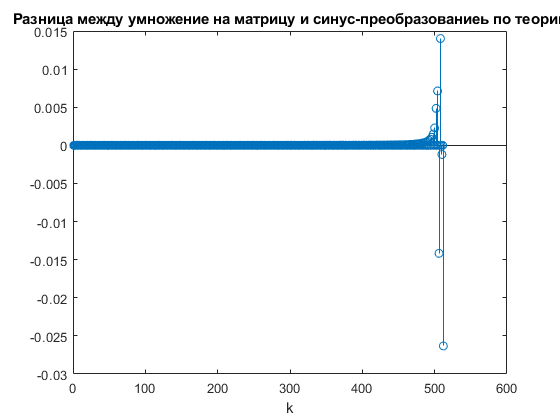

stem(Ruc2DSTon2NwithRu2withMirrTSTon2N(1:N)-RatucDST); title('Разница между умножение на матрицу и синус-преобразованиеь по теории'); xlabel('k');

max(Ruc2DSTon2NwithRu2withMirrTSTon2N(1:N)-RatucDST)

ans =    1.4012e-02

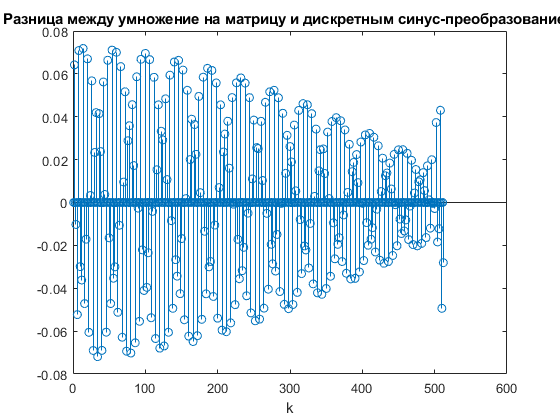

stem(Ruc2DSTon2NwithRu2withMirrDSTon2N(1:N)-RatucDST); title('Разница между умножение на матрицу и дискретным синус-преобразованием'); xlabel('k');

max(Ruc2DSTon2NwithRu2withMirrDSTon2N(1:N)-RatucDST)

ans =    7.1861e-02

Попробуем посчитать через свертку.

% u2mirr2 = u2.*iMirrTSTon2N;
% plot(u2mirr2)
% u2mirr2DST = sintr(u2mirr2);
% stem(u2mirr2DST(1:N)/sqrt(2))
% hold on
% stem(RatuDST)
% hold off
% stem(u2mirr2DST(1:N)/sqrt(2)-RatuDST)